# Matched Filter

## To put enough energy into this short pulse, we would need a very high peak power

## Transmit a longer Pulse but code it so that we can compress it on receive

### Pulse Compression

- Modulating the transmitted pulse and the correlating the received signal with the transmitted pulse.

Signal description

The simplest signal a pulse radar can transmit is a sinusodial amplitude pulse. A and carrier freq of f0 shorted by a rectangular function of width T. 

$s\left(t\right)={\mathrm{Ae}}^{\mathrm{j2}\pi f_0 t}$ if t is $0<t<T$ otherwise 0

The meaning of Convolution

Let's say that there is a Sound wave that we created. Overtime, the sound will decrease in time.

$S\left(t\right)=$ when 0< t < pi/2 sin(t), t<pi then 1, otherwise 0

t1 = [0:0.01:pi/2];
t2 = [pi/2+0.01:0.01:pi];
t3= [pi+0.01:0.01:5.002];
t= [t1 t2 t3];
y1 = sin(t1);
y2= ones(1,length(t2));
y3 = zeros(1,length(t3));
y = [y1 y2 y3];
subplot(1,2,1);
plot(t,y);
xlim([0 5]);
ylim([0 2]);

The remaining response is decreasing expoentially

Where the function is $e^{-t}$  

response = exp(-t)

response =     1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250    0.6188    0.6126


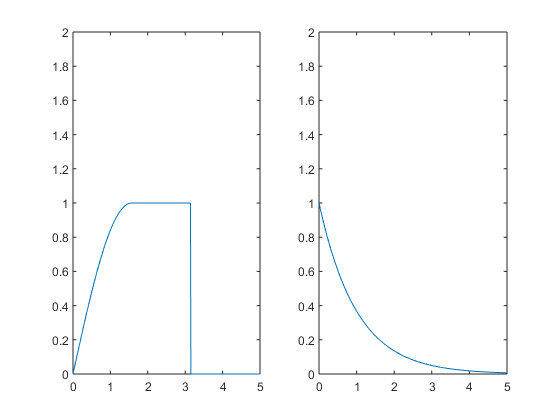

subplot(1,2,2);
plot(t,response);
xlim([0 5]);
ylim([0 2]);

At time t signal y is generated and as a result this signal is effected by the response funciton.

Let's say at t == 0 then the total effective response is 0 .

At time t = 0.1 the total effective response is [  sin(0.1)*1 + sin(0.09)*exp(0.01) + sin(0.08)*exp(0.02) ...sin(0)*exp(0.1) ] 0.01 

%For loop to calculated the result
partsum = 0;
sum =0;
for q = [0:0.01:0.1]
    partsum = sin(q)*exp(0.1-q)*0.01;
    sum = sum + partsum;
end
disp(sprintf('The sum of the sound at time = 0 is %f',sum));

The sum of the sound at time = 0 is 0.005664


#### Now we use the definition of Convolution which is $r\left(t\right)=\int_{-\infty }^{\infty } s\left(t\right)h\left(\tau -t\right)\mathrm{dt}$

%Example of how to use trapz
trapz(t,y)

ans = 2.5754

syms u;
int(sin(u),0,pi/2) + pi/2;

Which is the same value as trazp(t,y)

%So there is a function of y = s(t) and the response function  res(t)
% We filp the response function. 
%Solution Reverse the matrix,  left shift and the right side becomes zero
nresponse = fliplr(response); % filp the matrix
%We need to left shift 4.9 which consists 0.01
% 0 0.01 0.002 0.003 .... 5 The length of the vector t ? 
%5/0.01 500 ? 501 vectors 
nresponse = [nresponse(length(t)-10:length(t)) zeros(1,length(t)-11)];
actualre = nresponse.*y;
trapz(t,actualre)

ans = 0.0053

## Transfer Function

a Transfer functino of an electronic or control system component gives the divice's output for possible input.It is often represented as a graph, called a transfer curve or characteristic curve. The transfer function is used in the mathematical analysis of systems, particularly using the block diagram technique, in electronics and control theory.

The term "transfer function" is also used in the grequency domain analysis of systems using transform methods such as the Laplace transform; here it means the amplitude of the output as a function of the frequency of the input signal

We Understand the the process of Convolution means that the sum of the past function + the new function

## Matched Filter

- Simply speaking the matched filter is a reversed and time-delayed copy of the transmitted signal

- If $s_{\mathrm{tx}} \left(t\right)$ is the transmitted signal of the radar, the matched filter, $h\left(t\right)=s^* \left(\tau -t\right)$

Consider a finite-energy signal $s\left(t\right)$ that is the input to a filter with impulse response $h\left(t\right)$ transfer function H(f) and produces the output signal $y\left(\tau \right)=\int_{-\infty }^{\infty } s\left(\tau -t\right)h\left(t\right)\;\mathrm{dt}$

- What choise of h(t) will produce a maximum response at a given time $t_0$ ? That is , we are looking for a filter such that the global maximum of $y\left(\tau \right)$ occurs at $t_0$

- Yes the higher the h(t) the bigger the $y\left(\tau \right)$

- But If we restr

- aint the magnitude for the filter thing changes

#### $\int_{-\infty }^{\infty } |{h\left(t\right)}^2 |\mathrm{dt}=E=\int_{-\infty }^{\infty } |{s\left(t\right)}^2 |\mathrm{dt}$ (2) is the constraint

### 
$$y\left(t_0 \right)=\int_{-\infty }^{\infty } s\left(t_0 -t\right)h\left(t\right)\mathrm{dt}\le \sqrt{\int_{-\infty }^{\infty } |s\left(t_0 -t\right)|^2 \mathrm{dt}}\sqrt{\int_{-\infty }^{\infty } |h\left(t\right)|^2 \mathrm{dt}\;}=E$$


- Why this is the cauchy - s inequality ?

with the equality occurring if $h\left(t\right)=\lambda s\left(t_0 -t\right)\;\mathrm{with}\;\lambda >0$ where from (2) we get that $\lambda =1$ that is the filter with impulse response $h\left(t\right)=s\left(t_0 -t\right)$ produces the maximal response $y\left(t_0 \right)=E$ at the specified time $t_0$.

Therefore, the filter mathced to $s\left(t\right)$ at time $t_0$ or the matched filter for $s\left(t\right)$ at time $t_0$

In radar dynamics the matched filter is the reversed and time-delayed copy of the transmitted signal

$y_{\mathrm{rx}} \left(t\right)=\int_{-\infty }^{\infty } s_{\mathrm{tx}} \left(t-\tau \right)s_{\mathrm{rx}} \left(t\right)d\tau$ is the received graph ?

I think it should  be the opposite ?

No, 

Let's do a matched Filter Example !!

Transmit Signal $4\mathrm{uS},1\mathrm{MHz}\;\mathrm{simusoid}\;\mathrm{sampled}\;\mathrm{at}\;20\mathrm{Mhz}\left(0\ldotp 05\right)$

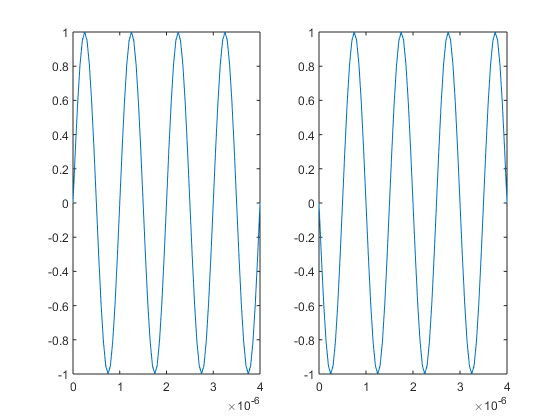

x = [0:0.05e-6:4e-6];
stx = sin(2*pi*1e6*x);
figure(2);
subplot(1,2,1)
plot(x,stx);
mf =  stx(1,length(stx):-1:1);  
subplot(1,2,2);
plot(x,mf);

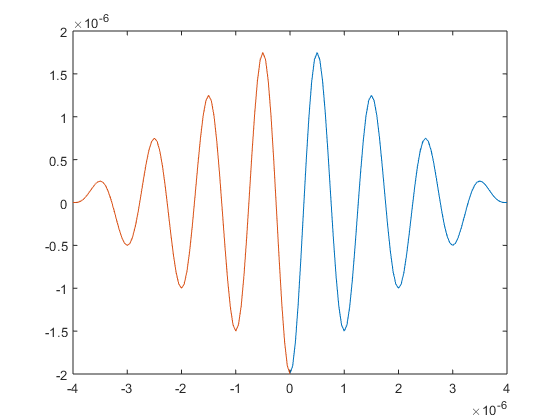

figure(3);
plot(x,matched_filter(stx,x));
hold on;
a = matched_filter(stx,x);
plot(-x,a)

function rep = matched_filter(a,c)
rep = zeros(1,length(a));
for n = [1:length(a)]
    an = a;
an=[zeros(1,n-1) an];
an = an(1:length(a));
temp = a.* an;
rep(1,n) = trapz(temp,c);
    
    
end
end